# Max's Analysis Script

## Load Necessary Saved Data

clear; clc; close all;
try
    loadData = load("C:\Users\maxcr\OneDrive\Class Materials\ASML Capstone\ASML_Code\Saved_Runs\ASML_EC_Sim_Run_zeroShot_13_Jan_2023_15_40_1.mat");
catch
  [fname,fpath] = uigetfile('C:\Users\maxcr\OneDrive\Class Materials\ASML Capstone\ASML_Code\Saved_Runs\','Select a dataset');
  loadData = load(fullfile(fpath,fname));
  disp(['Selected ', fullfile(fpath,fname)]);
end

Selected C:\Users\maxcr\OneDrive\Class Materials\ASML Capstone\ASML_Code\Saved_Runs\ASML_EC_Sim_Run_zeroShot_13_Jan_2023_16_19_15.mat


logsout = loadData.logsout;
ec = loadData.ec;
clear loadData fpath fname;

**WARNING: Much of the provided data will have ECdriveLaserGainCommand < 1. You **

**should only extract OL EUV data where ECdriveLaserGainCommand == 1, unless you have a special need for that lower energy data, e.g., ID of the transfer function from gain command to EUV.**

Ts = 20e-6; % nominal 50kHz sample rate
% generate a time vector equal to the length of the data vector
t = Ts*(1:length(ec.ECeuvValue))'-Ts;
% set the open-loop EUV and enab signal as inputs:
enab = ec.ECeuvValue > 1; % not terribly robust; exercise for the reader

## Plot the simulated closed-loop EUV side-by-side with the open-loop EUV

There's an error buried somewhere, which is causing some zero-EUV values to slip through. You will want to fix it at some point.

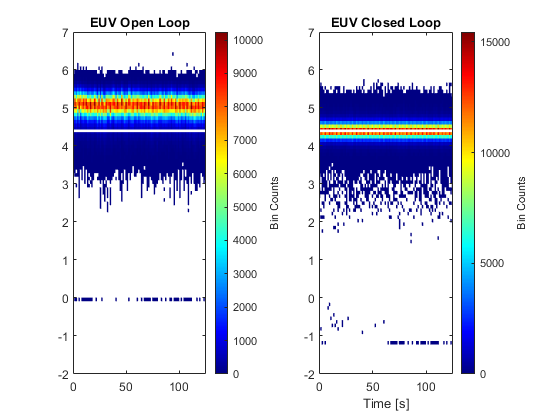

figure;
idx = logical(logsout.enab); % only want to show values where EUV is positive
h(1) = subplot(1,2,1);
binscatter(logsout.T_Eol_Scanner(idx),logsout.Eol_Scanner(idx),100)
yulim = max(ylim); % for linking the y-axes
colormap('jet') % add some pretty colors
hold on;
title('EUV Open Loop');
target = logsout.target;
target_array = target * ones(size(logsout.T_Ecl_Scanner));

plot(logsout.T_Ecl_Scanner(idx),target_array(idx),'LineWidth',2,'Color',"white");
xlim([min(logsout.T_Ecl_Scanner(idx)) max(logsout.T_Ecl_Scanner(idx))])

h(2) = subplot(1,2,2);
binscatter(logsout.T_Ecl_Scanner(idx),logsout.Ecl_Scanner(idx),100); hold on;
xlabel('Time [s]')
target = logsout.target;
target_array = logsout.target * ones(size(logsout.T_Ecl_Scanner));

plot(logsout.T_Ecl_Scanner(idx),target_array(idx),'LineWidth',2,'Color',"white");

ylim([min(ylim),yulim]);
xlim([min(logsout.T_Ecl_Scanner(idx)) max(logsout.T_Ecl_Scanner(idx))])
colormap('jet')
linkaxes(h,'y');
title('EUV Closed Loop');
xlabel('Time [s]')

clear idb DE 
% load slit
load Slit.mat %F vector is trapezoid filter

% index the bursts
burstIndex = cumsum([0;diff(logsout.enab(:))>0.5]);

## TOTAL DATASET DOSE ERROR STATISTICS

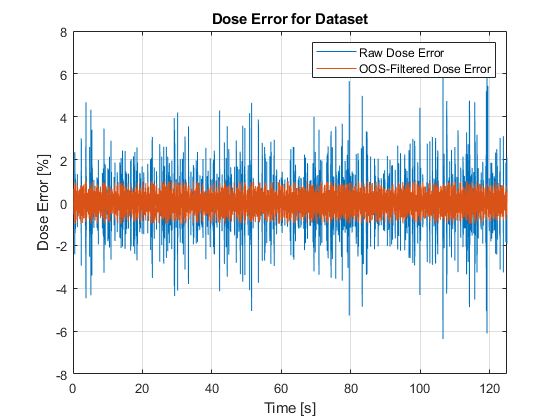

clear DE
logsout.enab = logical(logsout.enab); % grrrrr
GB = findgroups(burstIndex(logsout.enab));

temp = splitapply(@(t,e){computeDose1Burst(t,e,logsout.target,F)},...
  logsout.T_Ecl_Scanner(logsout.enab), ...
  logsout.Ecl_Scanner(logsout.enab), ...
  GB);
DE = nan(size(logsout.enab));
DE(logsout.enab) = vertcat(temp{:});

DE_filtered = remove_OOS(DE);
OOS_idx = getOOSlocations(DE);

figure;
plot(logsout.T_Ecl_Scanner,100*DE)%,'.')
hold on; grid on;
plot(logsout.T_Ecl_Scanner,100*DE_filtered);
xlabel("Time [s]")
ylabel("Dose Error [%]")
title('Dose Error for Dataset');
legend('Raw Dose Error','OOS-Filtered Dose Error');
xlim([0 max(logsout.T_Ecl_Scanner)])

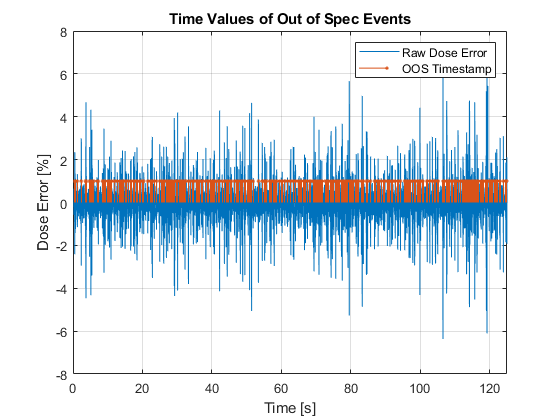

figure; clf;
plot(logsout.T_Ecl_Scanner,100*DE); hold on;
stem(logsout.T_Ecl_Scanner(OOS_idx == 1),OOS_idx(OOS_idx == 1),'.');
title('Time Values of Out of Spec Events'); grid on;
xlabel('Time [s]'); ylabel('Dose Error [%]');
legend('Raw Dose Error','OOS Timestamp'); xlim([0 max(logsout.T_Ecl_Scanner)])

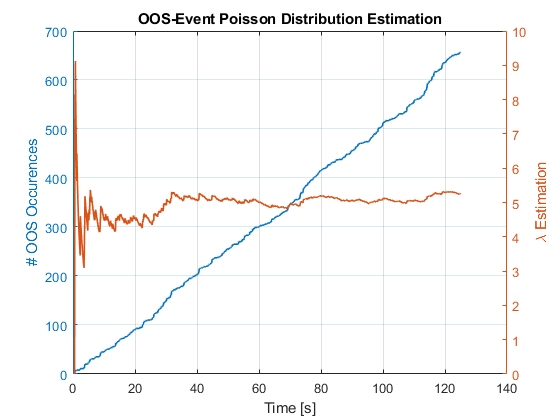

%change to negative OOS event

figure; clf;
yyaxis left
numOOS = cumsum(OOS_idx);
plot(logsout.T_Ecl_Scanner,numOOS,'LineWidth',1.25); grid on;
title('OOS-Event Poisson Distribution Estimation')
xlabel('Time [s]'); ylabel('# OOS Occurences');
yyaxis right
lambda = movmean(numOOS./logsout.T_Ecl_Scanner,1);
plot(logsout.T_Ecl_Scanner,lambda,'LineWidth',1.25);
ylabel('\lambda Estimation')

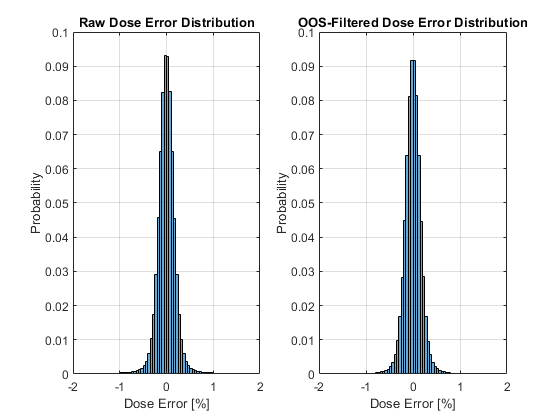


figure;
binwidth = 0.05;
subplot(1,2,1);
histogram(DE*100,'Normalization','probability','BinWidth',binwidth)
title('Raw Dose Error Distribution');
xlim([-2 2]); grid on; xlabel('Dose Error [%]'); ylabel('Probability');
ylim([0 0.1]);

subplot(1,2,2);
histogram(DE_filtered*100,'Normalization','probability','BinWidth',binwidth)
title('OOS-Filtered Dose Error Distribution');
xlim([-2 2]); xlabel('Dose Error [%]'); ylabel('Probability'); grid on;
ylim([0 0.1]);

DEmean = nanmean(DE); DEstd = nanstd(DE);
DEfiltmean = nanmean(DE_filtered); DEfiltstd = nanstd(DE_filtered);
disp('######### DOSE ERROR METRICS #########');

######### DOSE ERROR METRICS #########


%disp(['Raw Dose Error Mean = ', num2str(DEmean*100)]);
disp(['Raw Dose Error Std = ', num2str(DEstd*100)]);

Raw Dose Error Std = 0.2521


%disp(['OOS-Filtered Dose Error Mean = ', num2str(DEfiltmean*100)]);
disp(['OOS-Filtered Dose Error Std = ', num2str(DEfiltstd*100)]);

OOS-Filtered Dose Error Std = 0.17453


totalOOS = max(numOOS);
tmax = max(logsout.T_Ecl_Scanner);
disp(['Number of OOS-Events = ', num2str(totalOOS)]);

Number of OOS-Events = 657


disp(['Rate of OOS-Events = ', num2str(totalOOS/tmax), '/sec']);

Rate of OOS-Events = 5.256/sec


% ADD SKEWNESS OF DLGC AND DOSE ERROR

## Spectral Analysis

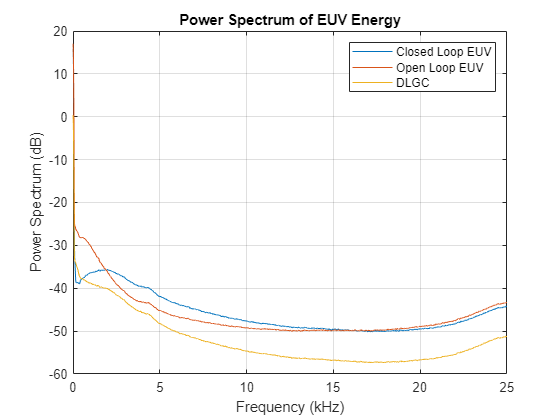

figure;
pspectrum(logsout.Ecl_Scanner(logsout.enab == 1),50e3); hold on;
pspectrum(logsout.Eol_Scanner(logsout.enab == 1),50e3);
pspectrum(logsout.dlgc(logsout.enab == 1),50e3);
title('Power Spectrum of EUV Energy');
legend('Closed Loop EUV','Open Loop EUV','DLGC');

## Energy Data Available for Control Purposes

Extract data arrays for EUV = ON (enab = 1) portions of the data. Do this for both open loop and closed loop energy for scanner/reticle energy and internal source energy.

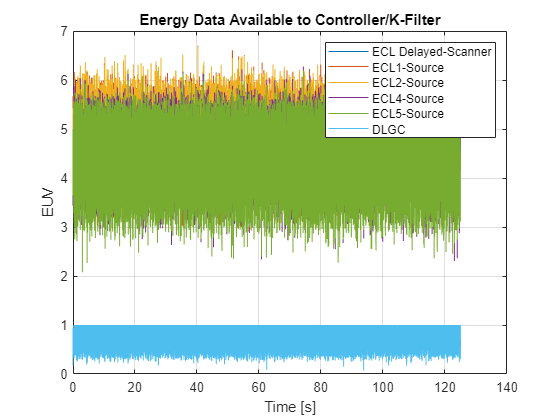

relidx = (logsout.enab == 1); %logical array - ideally just when the system is up and running
X = 1e3; Y = 1e2;
relidx = mod_relidx(relidx,X,Y);
figure;
plot(logsout.T_Ecl_Scanner_Delayed(relidx),logsout.Ecl_Scanner_Delayed(relidx)); hold on; grid on;
plot(logsout.T_Ecl_Source1(relidx),logsout.Ecl_Source1(relidx));
plot(logsout.T_Ecl_Source2(relidx),logsout.Ecl_Source2(relidx));
plot(logsout.T_Ecl_Source4(relidx),logsout.Ecl_Source4(relidx));
plot(logsout.T_Ecl_Source5(relidx),logsout.Ecl_Source5(relidx));
plot(logsout.T_dlgc(relidx),logsout.dlgc(relidx));
xlabel('Time [s]'); ylabel('EUV');
title('Energy Data Available to Controller/K-Filter')
 legend('ECL Delayed-Scanner','ECL1-Source','ECL2-Source','ECL4-Source','ECL5-Source','DLGC');

## n4sid Setup

Need to improve the input/output data so its just for the middle of a run, weird stuff (1s and 0s) are currently messing with hte n4sid model.

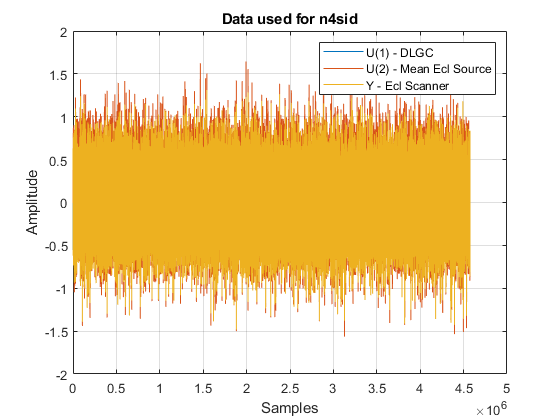

% u = [logsout.dlgc(relidx), logsout.Ecl_Source1(relidx), logsout.Ecl_Source2(relidx), logsout.Ecl_Source4(relidx), logsout.Ecl_Source5(relidx)];
% y = [logsout.Ecl_Scanner(relidx)];
 %data = iddata(y,u,Ts);

 Ecl_Sources = [logsout.Ecl_Source1(relidx), logsout.Ecl_Source2(relidx), logsout.Ecl_Source4(relidx), logsout.Ecl_Source5(relidx)];
 Ecl_Source_Mean = mean(Ecl_Sources,2);
 u = [logsout.dlgc(relidx)- mean(logsout.dlgc(relidx)), Ecl_Source_Mean - mean(Ecl_Source_Mean)];
 y = [logsout.Ecl_Scanner(relidx) - mean(logsout.Ecl_Scanner(relidx))];
 data = iddata(y,u,Ts);

figure; plot(u(:,1)); hold on; plot(u(:,2)); grid on; plot(y);
xlabel('Samples'); ylabel('Amplitude'); title('Data used for n4sid');
legend('U(1) - DLGC', 'U(2) - Mean Ecl Source', 'Y - Ecl Scanner')

## Perform SysID

 tic
 nx = 1:12;
 sys = n4sid(data,nx,'Feedthrough',1); %make sure Feedthrough is enabled
 toc

Elapsed time is 248.229406 seconds.


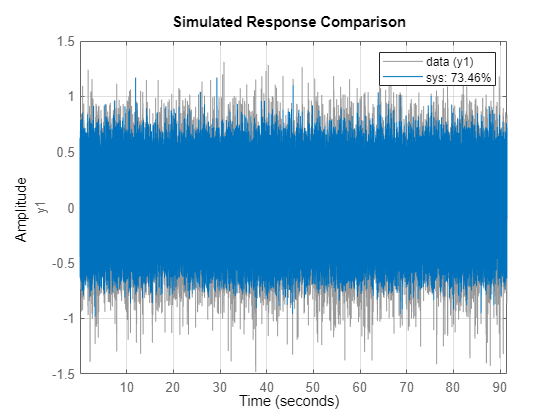

figure;
 compare(data,sys); grid on;

## Simulate SS Model

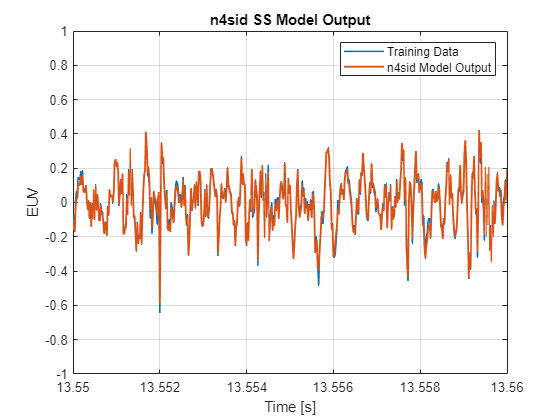

 %load('ssmodel.mat');
 len = size(u);
 smax = len(1);
 t = (0:Ts:((smax-1)*Ts)).';
 ysys = lsim(sys,u,t);

 figure;
  plot(t,y,'LineWidth',1.2); hold on; plot(t,ysys,'LineWidth',1.4); hold on; grid on;
 xlabel('Time [s]'); ylabel('EUV'); legend('Training Data','n4sid Model Output');
 title('n4sid SS Model Output'); xlim([13.55 13.56]); ylim([-1 1]);